%Apache Math Common
f_apache = @(x) 0.010639152685035536*x^2 - 10.496754906771143*x + 1896.6352591208715;
%Jama
f_jama = @(x) 9.836948239164106E-4*x^2 - 0.7590639992905102*x + 134.84914730392381;
%Matlab
f_matlab = @(x) 2.2859314185814158E-8*x^2 - 8.933348101898063E-6*x + 0.0016025072727272648;
%MatlabGPU
f_matlabGPU = @(x) 1.0096618381618518E-7*x^2 + 7.315969030967048E-6*x + 0.023519818181818718;

hold on;
plot1 = fplot(f_apache, [0, 10E10], 'LineWidth',2); 

label1 = 'Apache';
hold off;

hold on;
plot2 = fplot(f_jama, [0, 10E10], 'LineWidth',2); 

label2 = 'Jama';
hold off;

hold on;
plot3 = fplot(f_matlab, [0, 10E10], '+', 'LineWidth',2); 

label3 = 'Matlab';
hold off;

hold on;
plot4 = fplot(f_matlabGPU, [0, 10E10], '-.', 'LineWidth',2); 

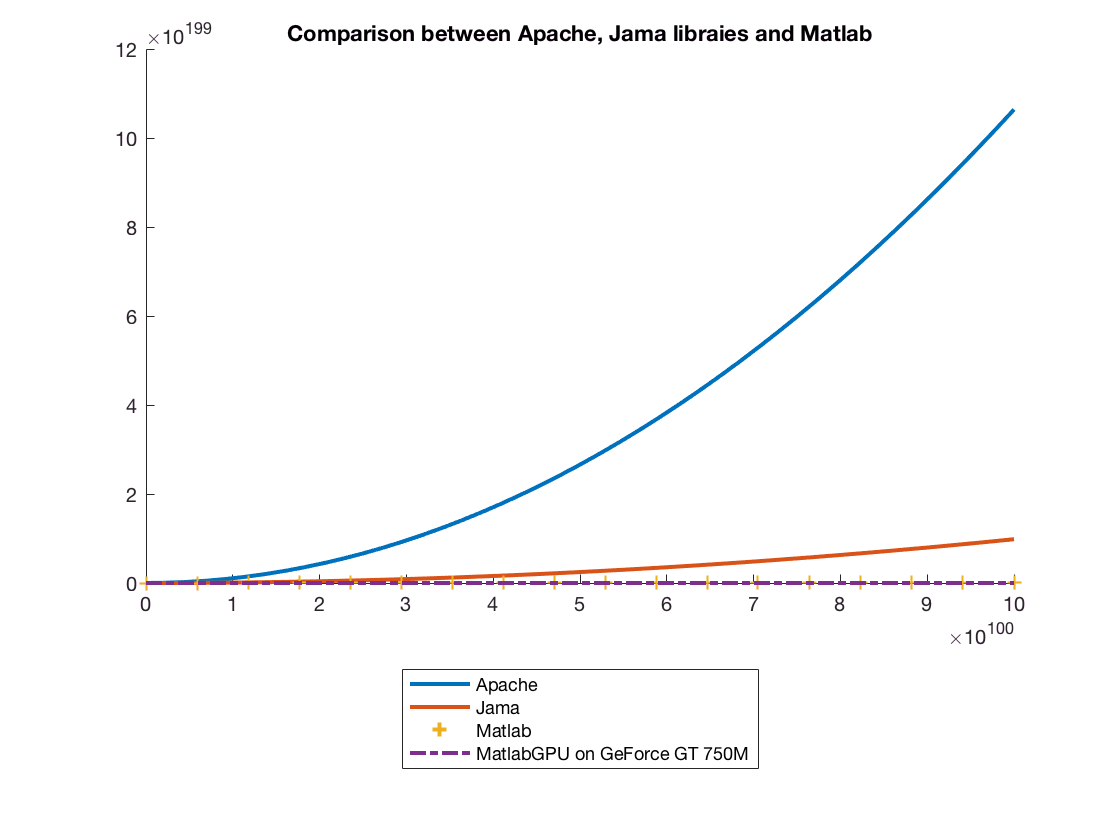

label4 = 'MatlabGPU on GeForce GT 750M';
hold off;

title('Comparison between Apache, Jama libraies and Matlab');
legend(label1, label2, label3, label4,'Location','southoutside');